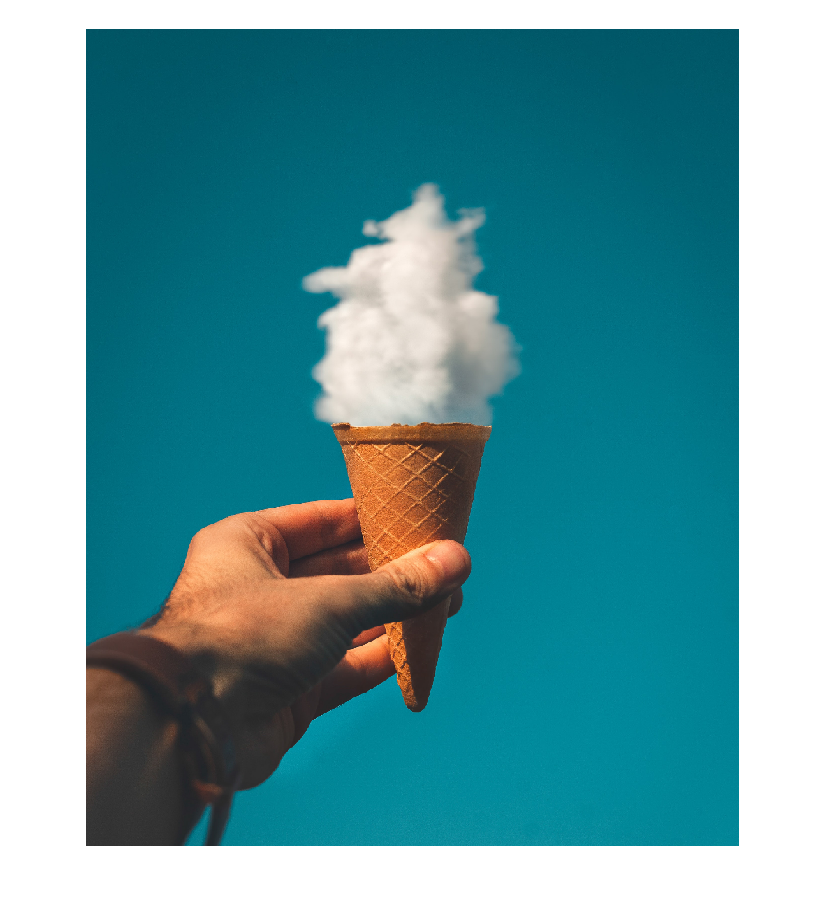

% Add your file path to any picture here
A = imread(['clouds-conceptual-cone-1262302.jpg']); %images from https://www.pexels.com/
imshow(A);

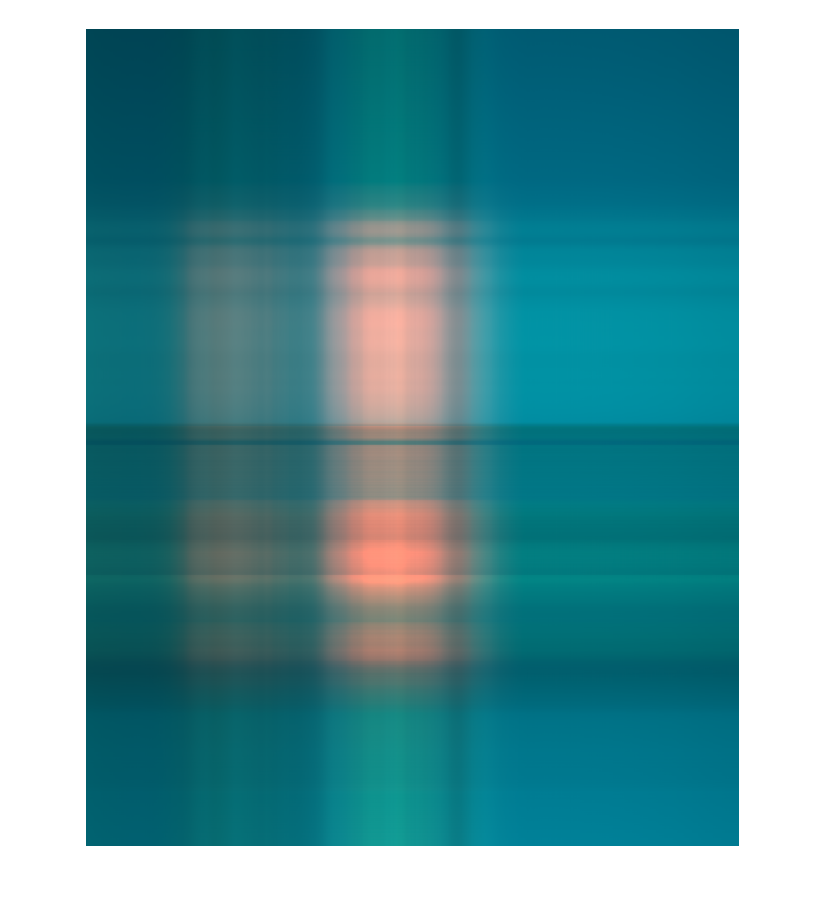

   1.0e+05 *

    1.8677
    0.9548
    0.4283
    0.3760
    0.3172
    0.2524
    0.2035
    0.1811
    0.1449
    0.1363

   1.0e+05 *

    3.3578
    0.5601
    0.4124
    0.2813
    0.1765
    0.1322
    0.1280
    0.1094
    0.0768
    0.0738

   1.0e+05 *

    3.6236
    0.6523
    0.5051
    0.2638
    0.1632
    0.1198
    0.1106
    0.0964
    0.0930
    0.0685



% use just the first singular value
compress(A,1,1);

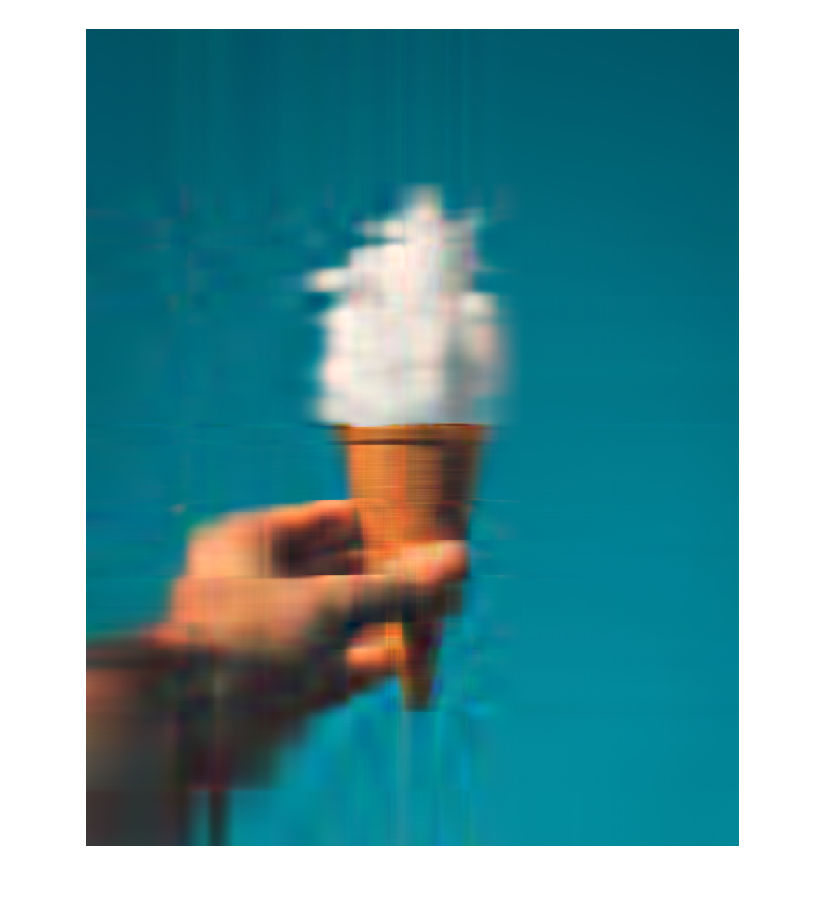

   1.0e+05 *

    1.8677
    0.9548
    0.4283
    0.3760
    0.3172
    0.2524
    0.2035
    0.1811
    0.1449
    0.1363

   1.0e+05 *

    3.3578
    0.5601
    0.4124
    0.2813
    0.1765
    0.1322
    0.1280
    0.1094
    0.0768
    0.0738

   1.0e+05 *

    3.6236
    0.6523
    0.5051
    0.2638
    0.1632
    0.1198
    0.1106
    0.0964
    0.0930
    0.0685



% use the first 10 singular values
compress(A,1,10);

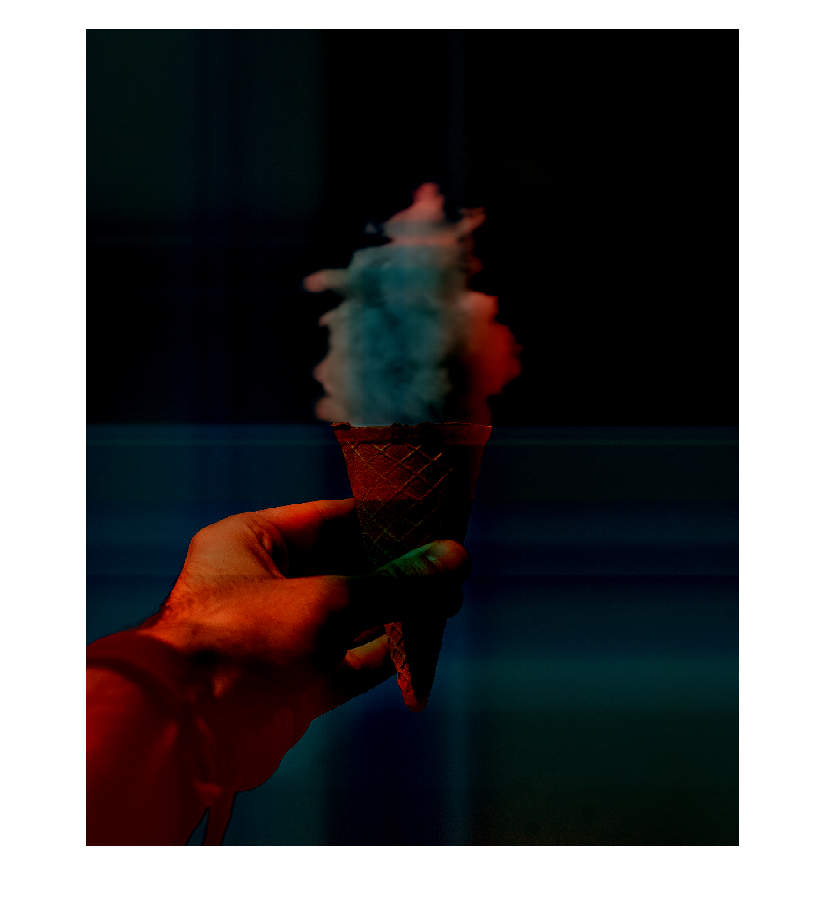

   1.0e+05 *

    1.8677
    0.9548
    0.4283
    0.3760
    0.3172
    0.2524
    0.2035
    0.1811
    0.1449
    0.1363

   1.0e+05 *

    3.3578
    0.5601
    0.4124
    0.2813
    0.1765
    0.1322
    0.1280
    0.1094
    0.0768
    0.0738

   1.0e+05 *

    3.6236
    0.6523
    0.5051
    0.2638
    0.1632
    0.1198
    0.1106
    0.0964
    0.0930
    0.0685



% singular values 2 through 1000
compress(A,2,1000);

The function 'compress' takes as input:

  A - a 3D matrix representing an image

  first - the first singular value to use

  last - the las singular value to use

also prints the first 10 singular values of each color

and outputs: the compressed image array

function final = compress(A, first,last)
    
    c1 = double(A(:,:,1));
    c2 = double(A(:,:,2));
    c3 = double(A(:,:,3));
    
    [U1,S1,V1] = svd(c1);
    [U2,S2,V2] = svd(c2);
    [U3,S3,V3] = svd(c3);
    
    U11 =  U1 * S1;
    U22 =  U2 * S2;
    U33 =  U3 * S3;

    US1 = U11(:, first:last);
    US2 = U22(:, first:last);
    US3 = U33(:, first:last);

    VS1 = V1(:, first:last);
    VS2 = V2(:, first:last);
    VS3 = V3(:, first:last);

    UR1 = US1 * VS1';
    UR2 = US2 * VS2';
    UR3 = US3 * VS3';

    final(:,:,1) = UR1;
    final(:,:,2) = UR2;
    final(:,:,3) = UR3;

    s1 = diag(S1);
    s2 = diag(S2);
    s3 = diag(S3);
    
    imshow(final/255);
    disp(s1(1:10))
    disp(s2(1:10))
    disp(s3(1:10))
end